clear;clc;close all;
fprintf('init.. done');

init.. done

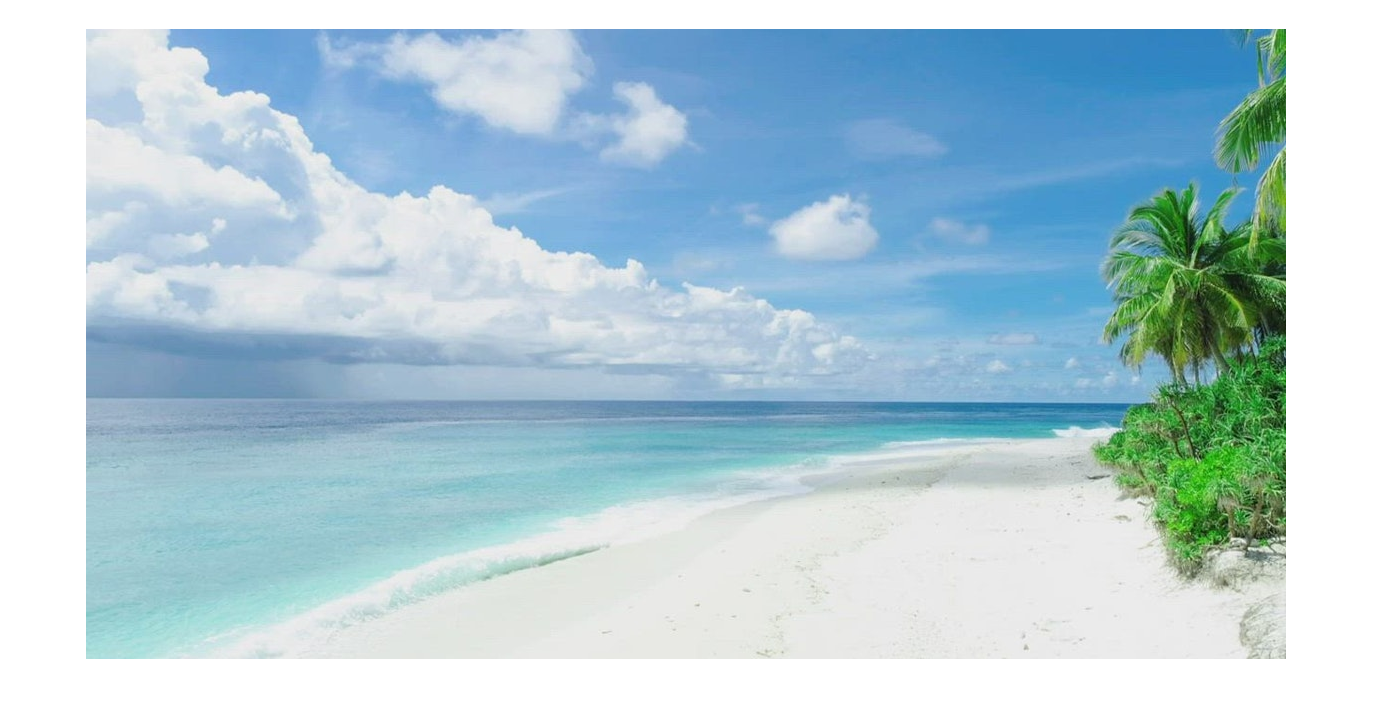

img = imread('imgs/img01.jpg');
imshow(img)

net = alexnet;
categoryNames = net.Layers(end).ClassNames;
fprintf('load pre-trained AlexNet...done');

load pre-trained AlexNet...done

img = imresize(img, [227,227]); % resize for the pre-trained alexnet
[prediction, scores] = classify(net, img);
prediction

prediction = categorical
     seashore 


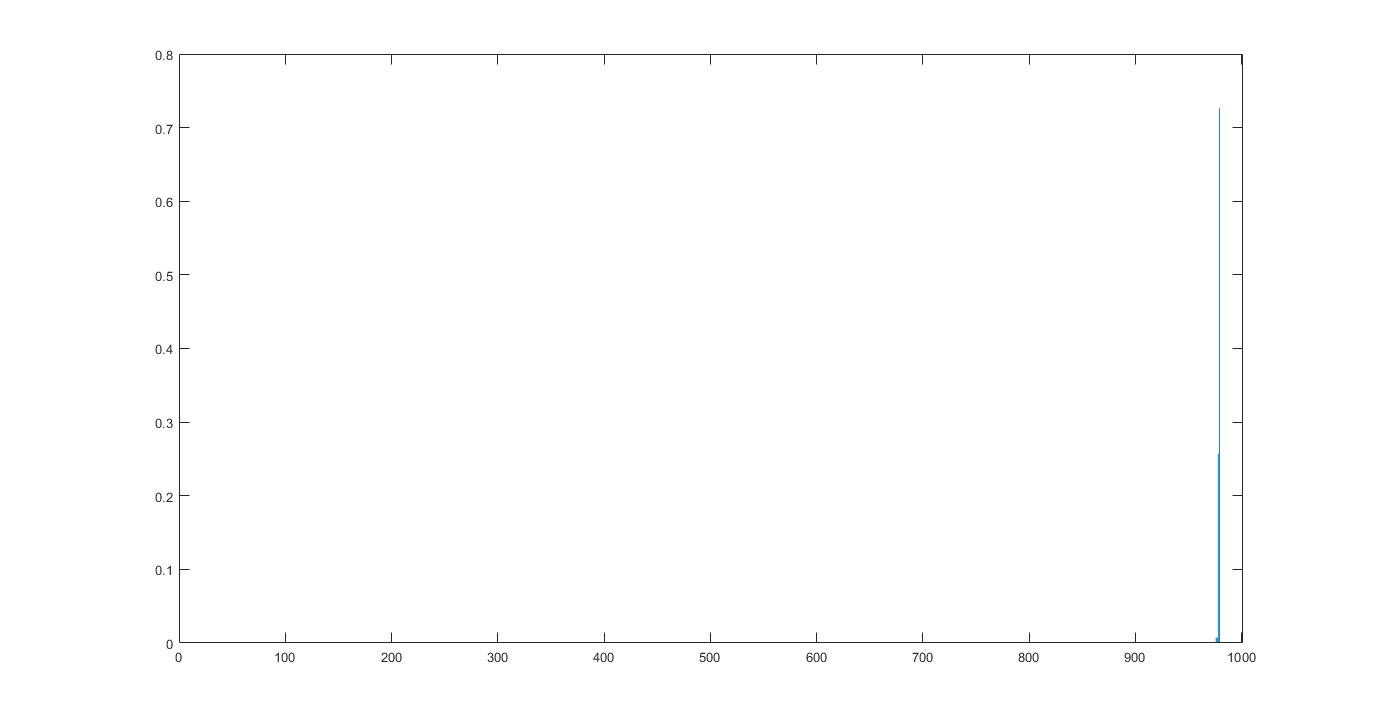

bar(scores); % display in bar chart... too many results

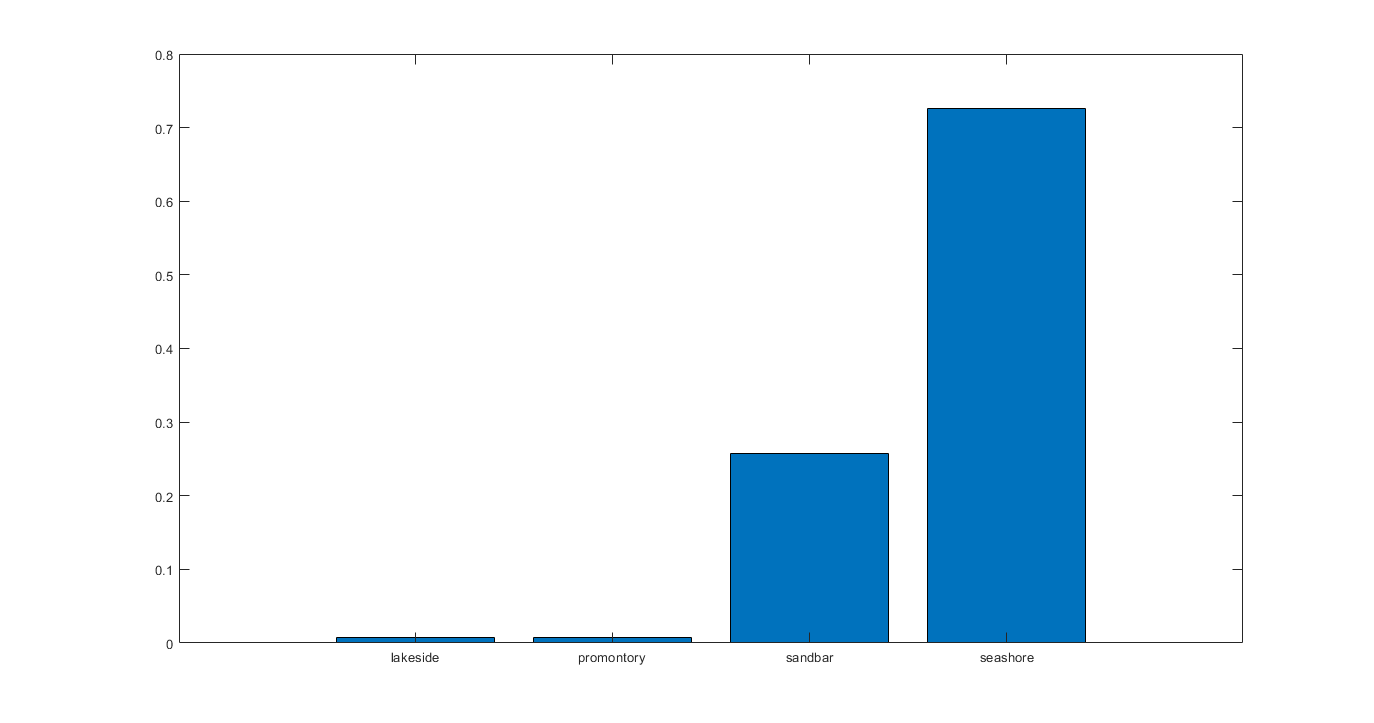

highScoresOnly = scores > 0.005;
bar(scores(highScoresOnly));
xticklabels(categoryNames(highScoresOnly));